# Image Enhancement in the Spatial Domain

Created time : 2024/3/7 11:34

學號 : 109321019    姓名 : 涂价弘

## Lab-5 (last week)

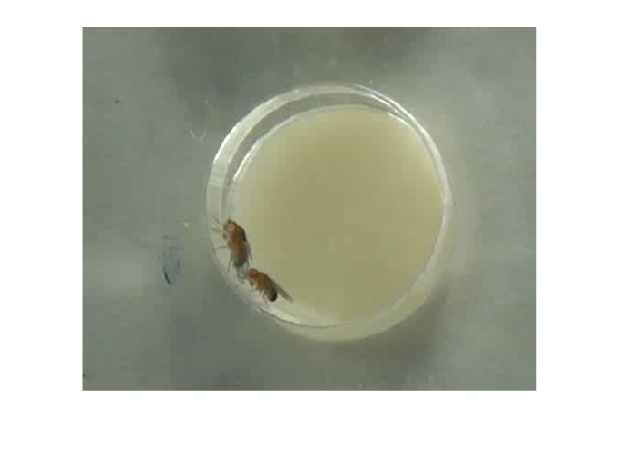

clf('reset');
video = VideoReader('./video/fruit_fly.avi');

while hasFrame(video)
frame = readFrame(video);
frame = frame(1:400, 1:500, :);
imshow(frame);
break
end

clf('reset');
video = VideoReader('./video/fruit_fly.avi');

frame = readFrame(video);
frame = frame(1:400, 1:500, :);
imshow(frame);
% impixelinfo

## Exercise-1

clf('reset');
img = imread('./images/3/Fig3.04(a).jpg');

subplot(1, 2, 1), imshow(img)
title("Origin")
negative = 255.0 - double(img);
subplot(1, 2, 2), imshow(negative, [])
title("Negative")

## Exercise-2

clf('reset');
img = imread('./images/3/Fig3.05(a).jpg');

subplot(1, 2, 1), imshow(img)
title("Origin")
c = 255 / log(256);
transform = c * log(1 + double(img));
subplot(1, 2, 2), imshow(transform, [])
title("Log")

## Exercise-3

clf('reset');
img = imread('./images/3/Fig3.08(a).jpg');

subplot(2, 2, 1), imshow(img)
title("origin")

% LUT: 預先計算好每個 pixel 的結果
% 目標圖像輸入的 pixel 當 index 來查找計算結果

tic
test = double(img).^0.6;
toc

tic
LUT1 = (0:255).^0.6;
toc

% LUT faster than dot calculation

LUT2 = (0:255).^0.4;
LUT3 = (0:255).^0.3;

subplot(2, 2, 2), imshow(LUT1(img + 1), [])
title("\gamma = 0.6")
subplot(2, 2, 3), imshow(LUT2(img + 1), [])
title("\gamma = 0.4")
subplot(2, 2, 4), imshow(LUT3(img + 1), [])
title("\gamma = 0.3")

clf('reset');
img = imread('./images/3/Fig3.09(a).jpg');

subplot(2, 2, 1), imshow(img)
title("origin")

LUT1 = (0:255).^3;
LUT2 = (0:255).^4;
LUT3 = (0:255).^5;

subplot(2, 2, 2), imshow(LUT1(img + 1), [])
title("\gamma = 3")
subplot(2, 2, 3), imshow(LUT2(img + 1), [])
title("\gamma = 4")
subplot(2, 2, 4), imshow(LUT3(img + 1), [])
title("\gamma = 5")